x = discretize_load(4,27.25,2001)

x =        3.4063        11928
       10.219       8519.9
       17.031       5111.9
       23.844         1704


format shortG
[y, moment] = wall_reactions(x)

y =         27264


moment =    2.5538e+05


error = moment_error(x,27.25,2001)

error =         21584


errors = loopP(2001,27.25)

errors =    1.1735e+05        24486        15888        21584        21886        20617        18936        17231        18499        18914        18835        18467        17935        18090        18364        18410        18296        18069        17974        18171        18239        18207        18098        17930        18082        18151        18152        18098        18000        18034


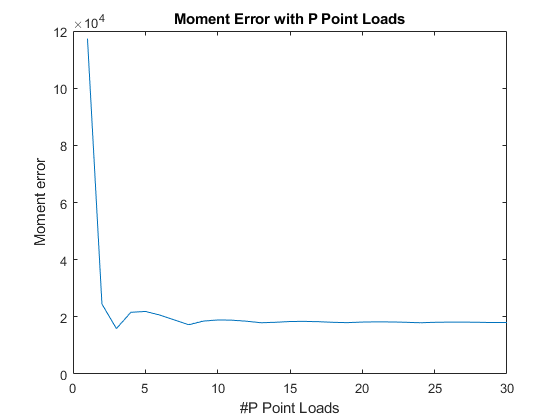

plot((1:30),errors)
xlabel("#P Point Loads")
ylabel("Moment error")
title("Moment Error with P Point Loads")

Midpoint rule approximation.

function errorP = loopP(w,L)
    for k = 1:30
        f = discretize_load(k,L,w);
        errorVec(k) = moment_error(f,L,w);
    end
    errorP = errorVec;
end
function error = moment_error(matrix,L,w)
    point = (3*L)/16;
    holderMatrix = matrix(matrix(:,1) >= point,:);
    newMatrix = [point - holderMatrix(:,1), holderMatrix(:,2)];
    Mpoint = 0;
    for d = 1:size(newMatrix,1)
        Mpoint = Mpoint - (newMatrix(d,1) * newMatrix(d,2));
    end
    Mpoint;
    Mdist = ((w * point^2) / 3) - ((L * w * point) / 2) + ((w * (1 - point / L) * point^2)/6);
    error = Mpoint + Mdist;
end
function [Fy, M] = wall_reactions(load)
    Fy = sum(load(:,2));
    M = 0;
    if size(load,1) == 1
        M = (load(1,1)*load(1,2));
    else
        for j = 1:length(load)
            M = M + (load(j,1)*load(j,2));
        end
    end
end
function resForce = discretize_load(p,L,w) % using midpoint approximation, assuming uniform load
    dx = L/p;
    resForce = zeros(p,2);
    if p == 1
        resForce(2,1) = L/2;
        resForce(2,2) = w*(1-(resForce(2,1)./L))*dx;
        resForce(1,:) = [];
    else
        for i = 1:p 
            resForce(1,1) = dx/2; % since it's just the center of each cut, start with dx/2
            resForce(i+1,1) = resForce(i,1) + dx; % every other point is a multiple of dx away
            resForce(i,2) = w*(1-(resForce(i,1)./L)) * dx;
        end
        resForce(end,:) = [];
    end
end